## Lec 13:

## Ex1

Determine for systems which is observable:

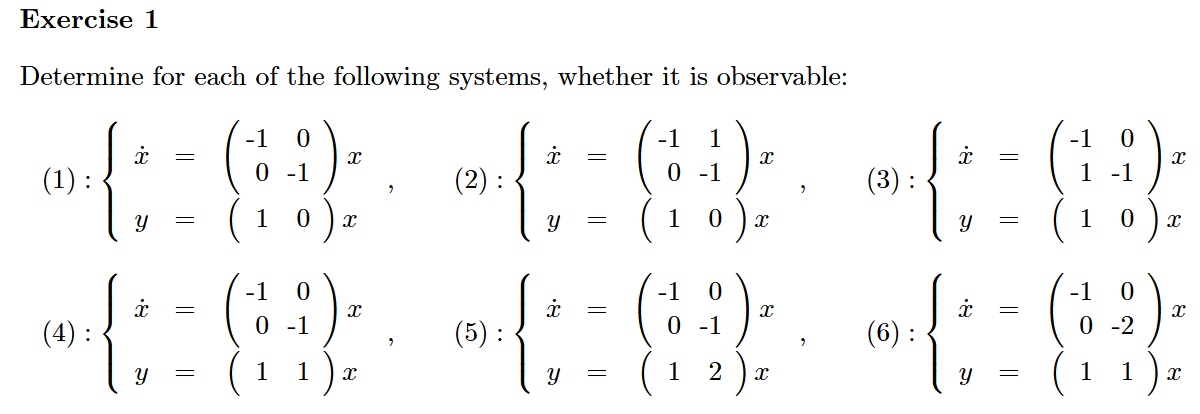


$$O=\left\lbrack \begin{array}{c}
C\\
\mathrm{CA}
\end{array}\right\rbrack ,\det \left(O\right)\not= 0\;s\aa \;\mathrm{er}\;\mathrm{den}\;\mathrm{observable}$$


1) $O=\left\lbrack \begin{array}{cc}
\;1 & 0\\
-1 & 0
\end{array}\right\rbrack ,\det \left(O\right)=0\;\mathrm{non}\;\mathrm{observable}$

;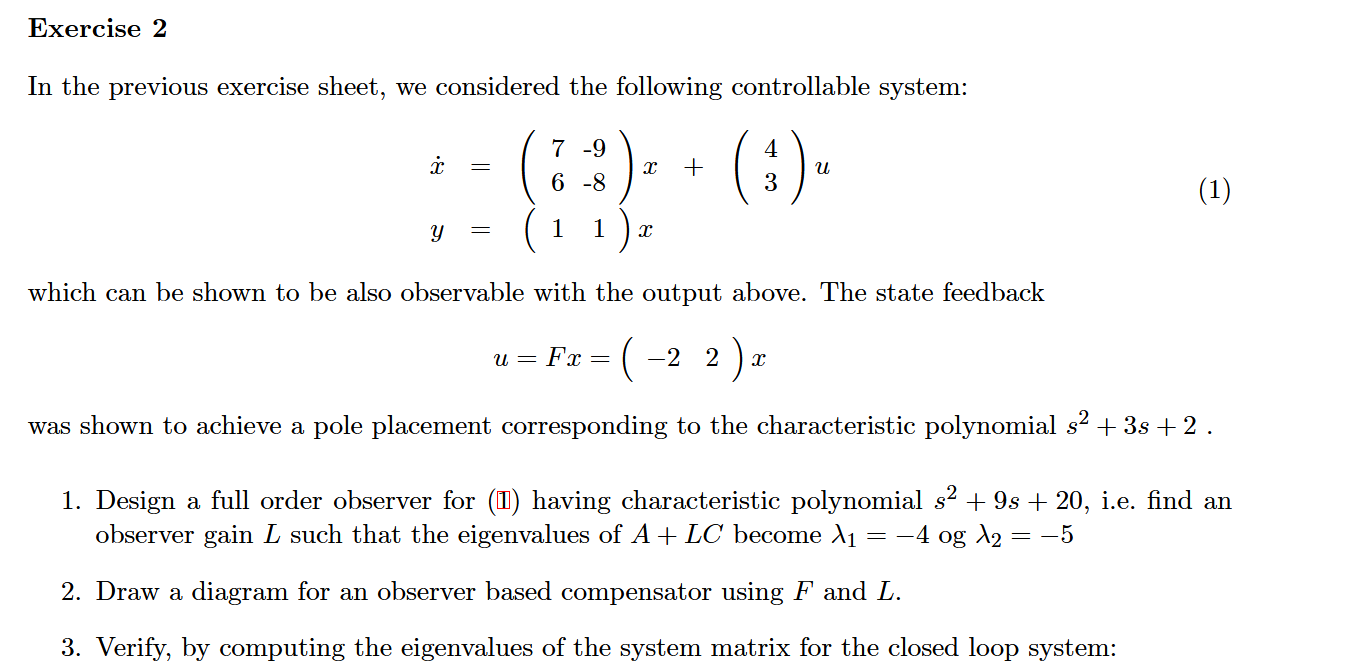

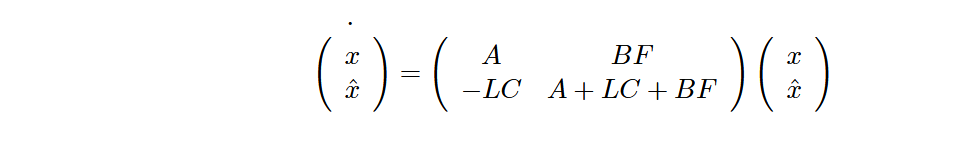

**1) og 2) **

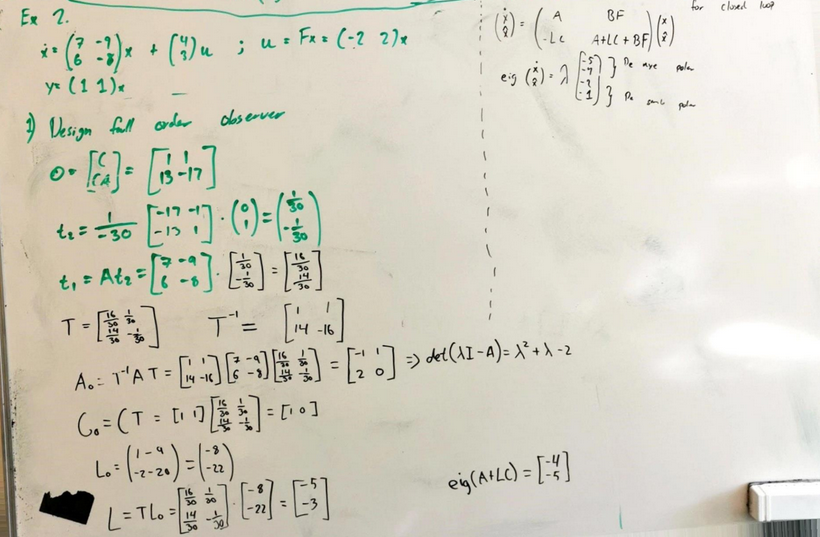

close all
clear

xdot = [7 -9; 6 -8];

y = [1 1];

O = [y; y*xdot];
t2 = inv(O)*[0;1]; 
t1 = xdot*t2;
T = [t1(1) t2(1); t1(2) t2(2)];
Ao = inv(T)*xdot*T;
Co = y*T;
Lo = [-8; -22];
L = T*Lo;
eig(xdot + L*y);

ans =                         -4
                        -5


ans =                         -5
                        -4


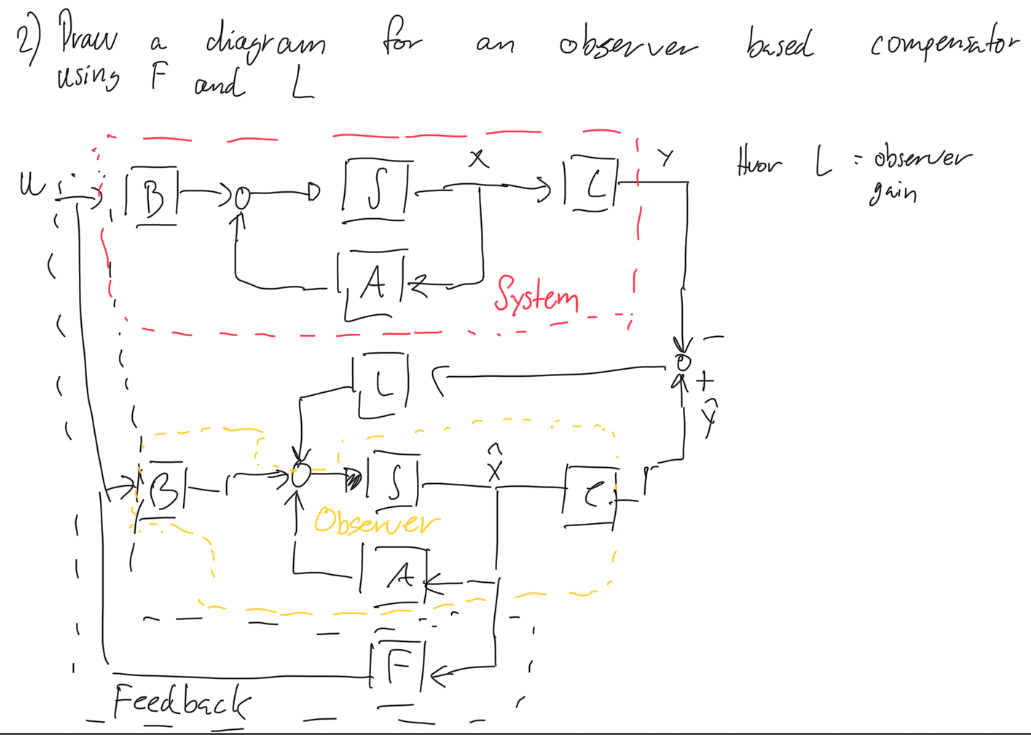

**3)**

closedloop = [xdot [4;3]*[-2 2]; -L*y (xdot + L*y + [4;3]*[-2 2])];
eig(closedloop)

ans =          -5.00000000000002
         -3.99999999999996
         -2.00000000000001
         -1.00000000000001
